# Data Visualization with MATLAB

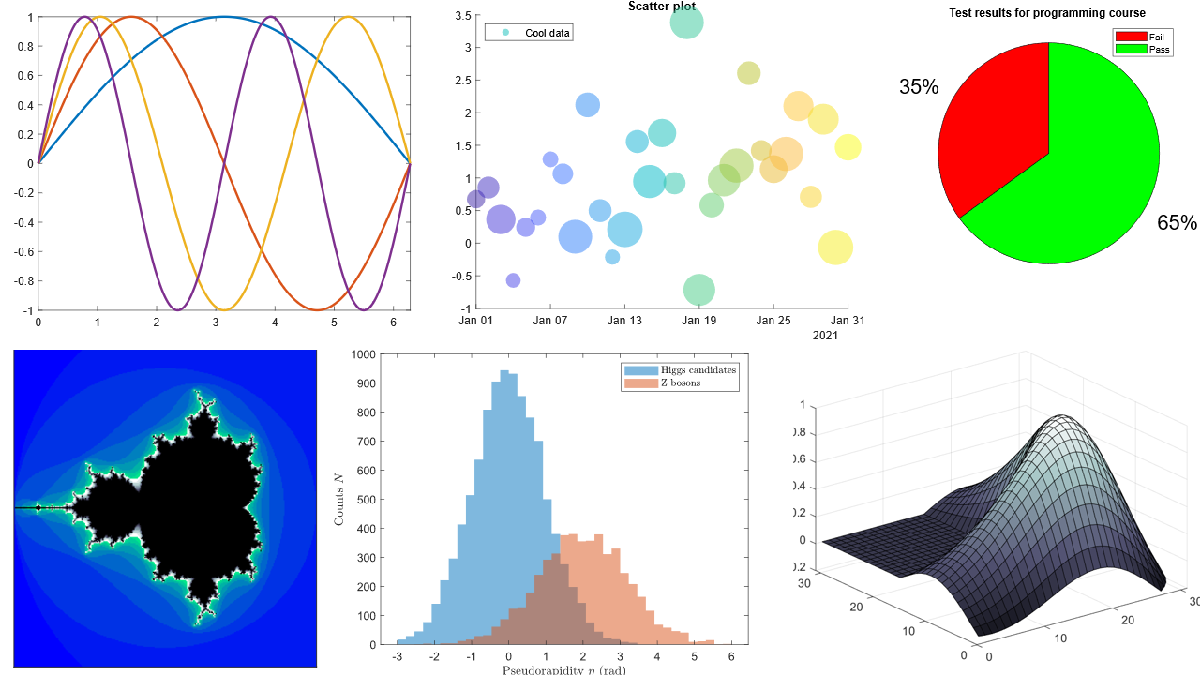

All plots above were made purely in MATLAB! See [this live script](https://github.com/simonthor/kth-matlab-ambassador/blob/master/Seminars/Data%20Visualization%20with%20MATLAB/marketing/banner.mlx).

# Introduction

## Presentation

All material used during this webinar is available on Github: [https://github.com/simonthor/kth-matlab-ambassador/tree/master/Seminars/Data%20Visualization%20with%20MATLAB](https://github.com/simonthor/kth-matlab-ambassador/tree/master/Seminars/Data%20Visualization%20with%20MATLAB)

## Zoom Poll

A quick introductory Zoom poll will be launched now.

# Demo

clf;

## `plot`

The most commonly used command: `plot`. This will plot x and y data in 2D.

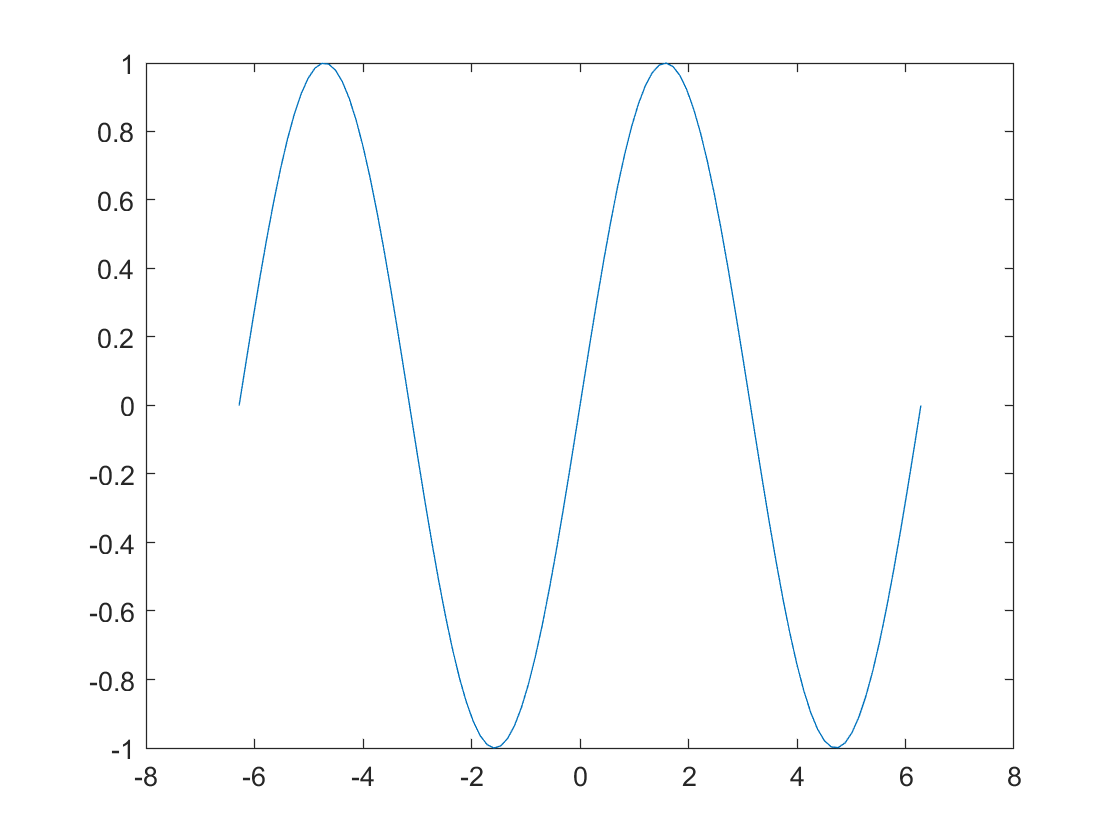

x = linspace(-2*pi, 2*pi, 100);
plot(x, sin(x));

You can add more things to a plot using `hold on` and `hold off`

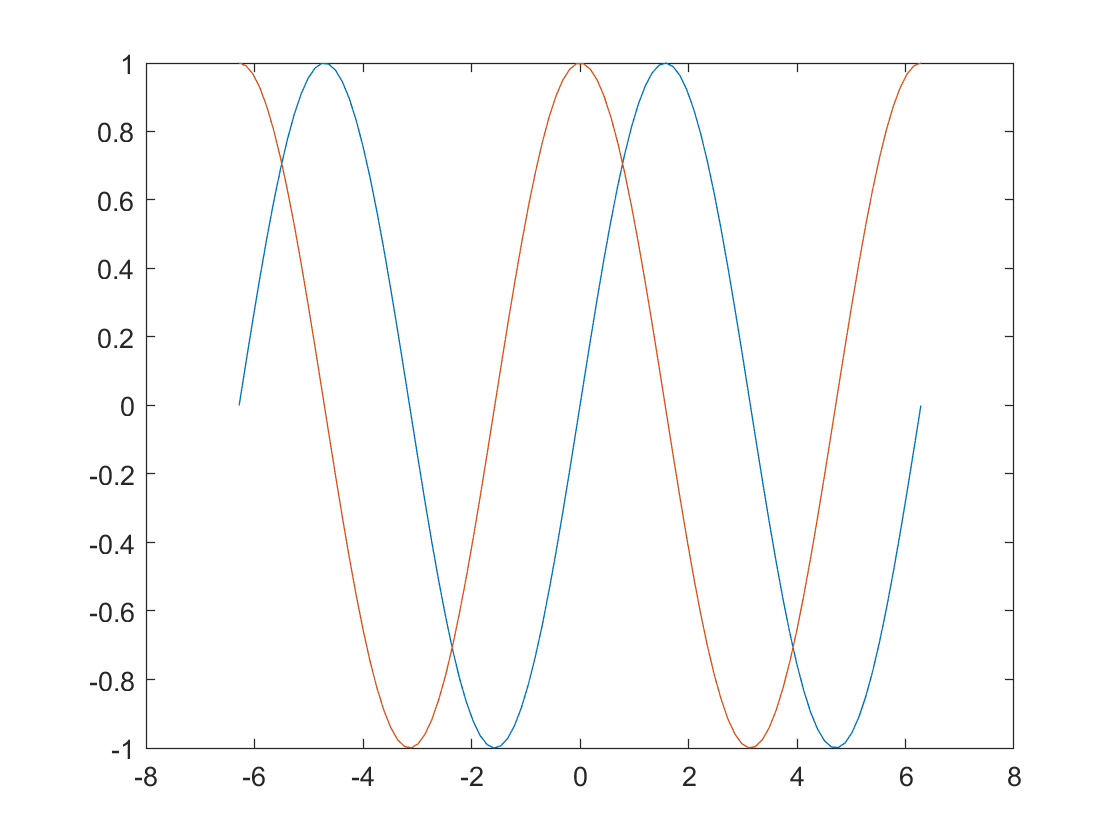

hold on
plot(x, cos(x));
hold off

Using `hold on` and `hold off` in a Live script might result in some weird behavior because the plot is diplayed for each cell but is also modified. For this demo, I will therefore create separate figures for each of demonstration.

This can be done with `figure`

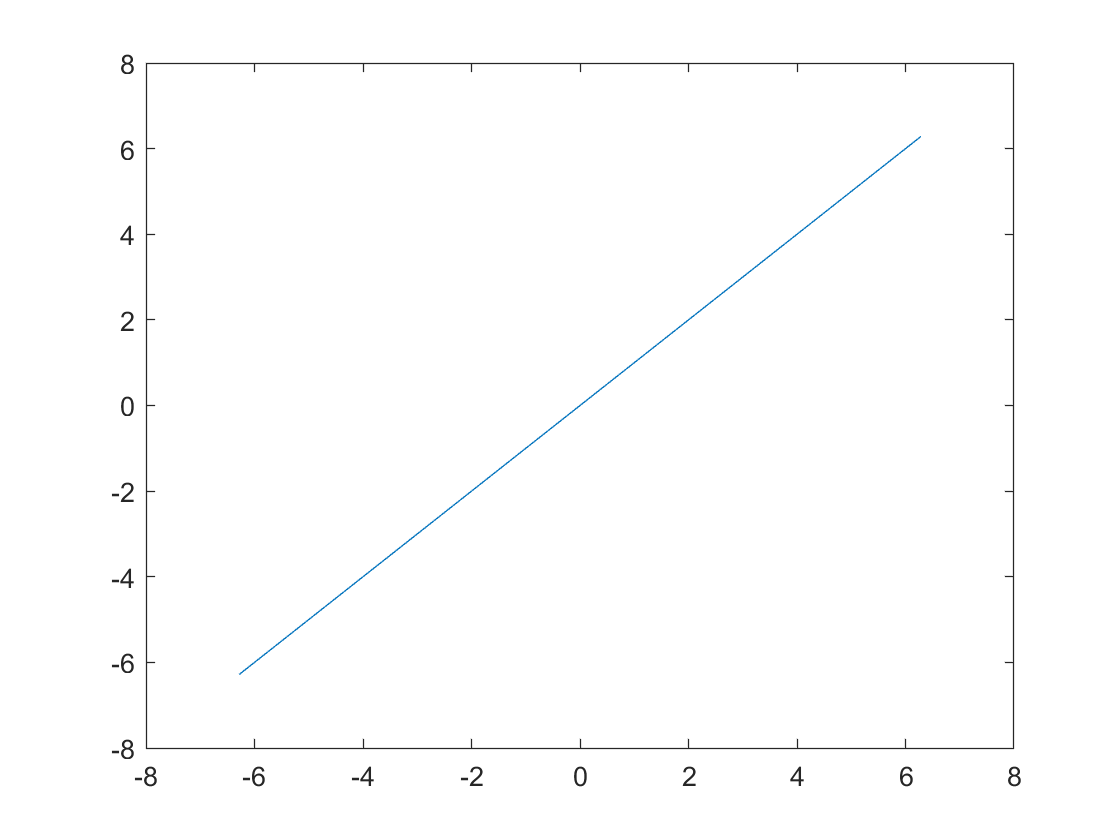

figure;
plot(x, x);

One can also plot multiple lines with one call to `plot`

multirow_y = [sin(x)
              cos(x)
              atan(x)];
size(multirow_y)

ans =      3   100


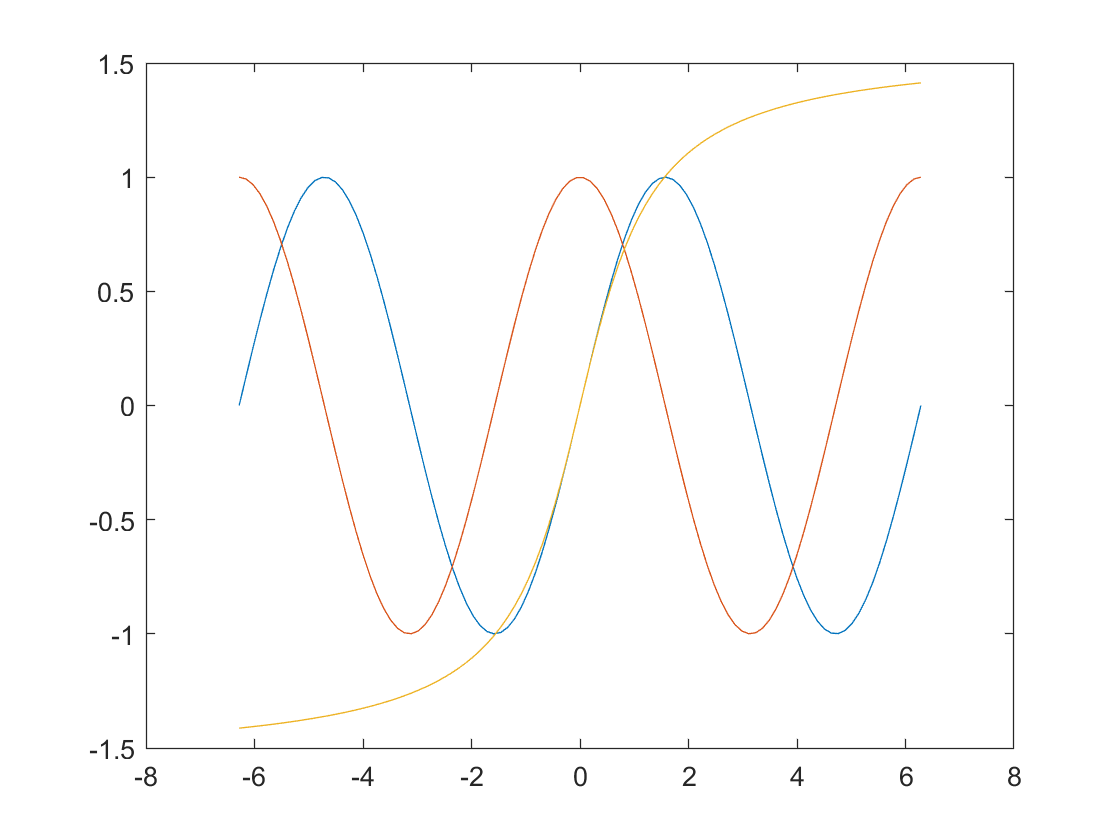


figure;
plot(x, multirow_y);

Different lines can have separate x and y values, the same x values but different y values and vice versa. The example above has the same x values but different y values.

`plot` accepts many customizations

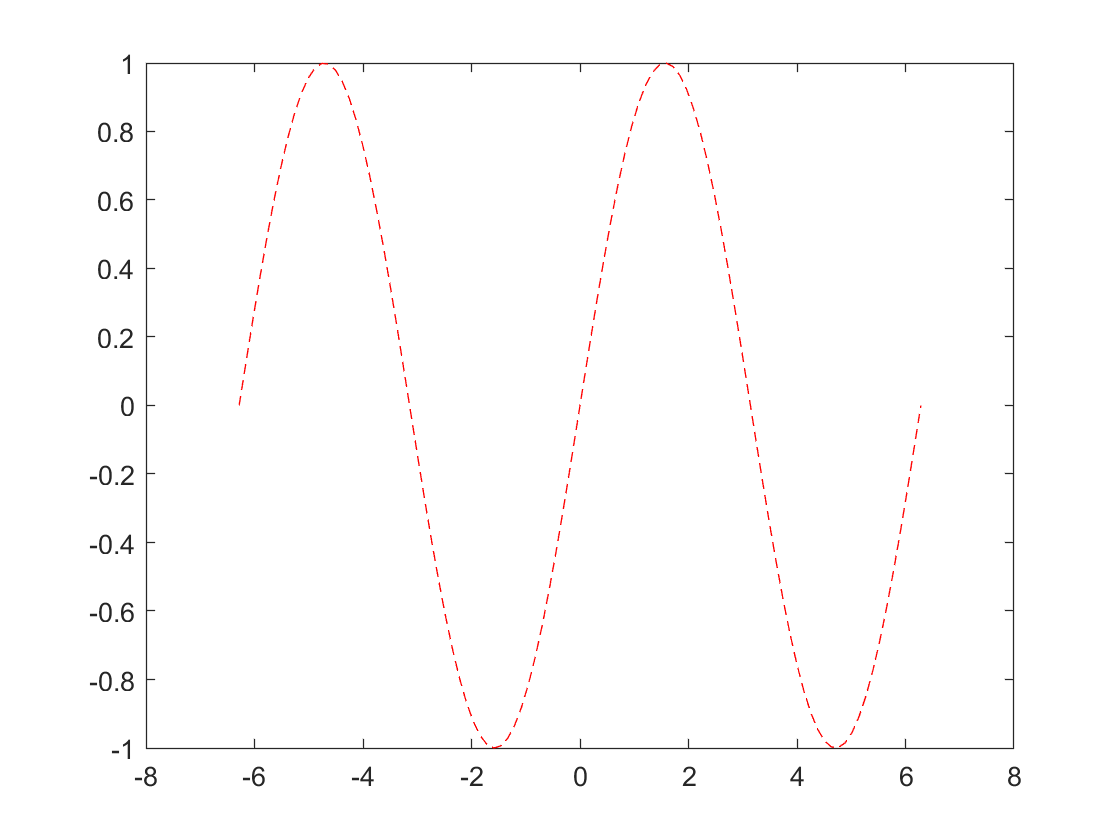

figure;
% Try yourself with MATLAB's autocomplete! Type , to explore the options
plot(x, sin(x), "Color","red", "LineStyle","--");

## Other plotting functions

There are many many more plot functions than `plot:`

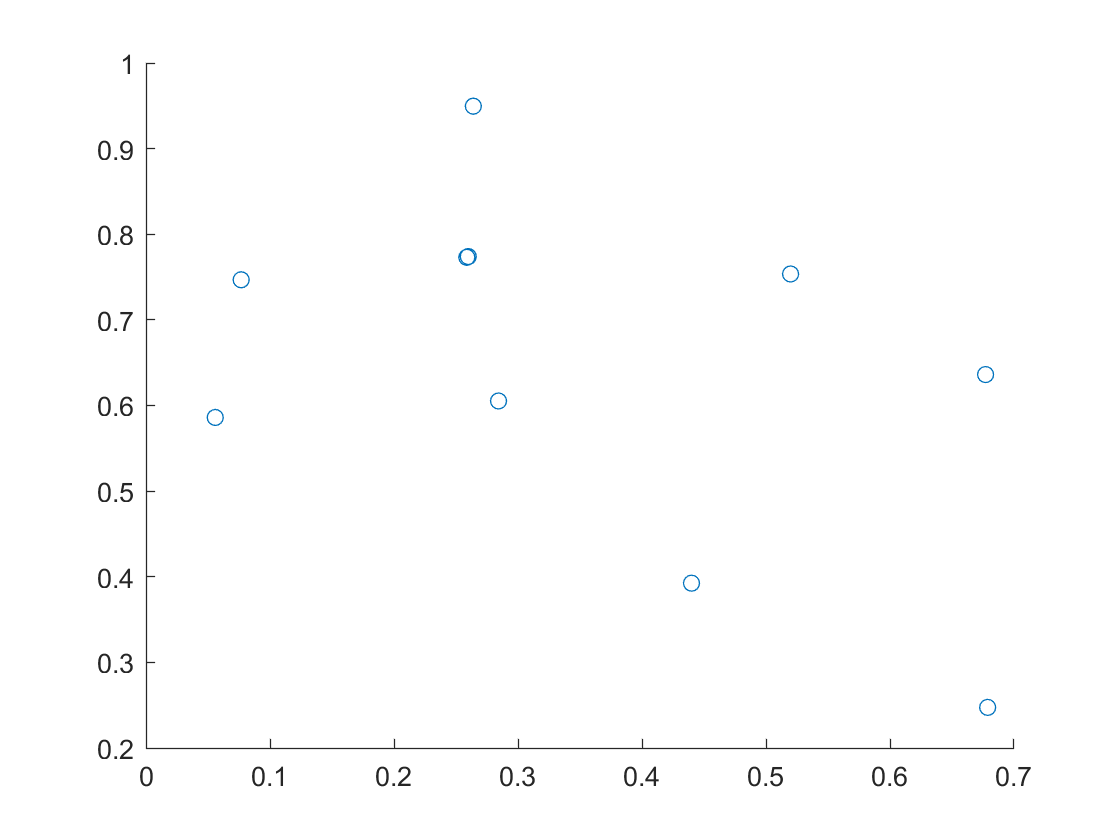

figure;
scatter(rand(10, 1), rand(10, 1));

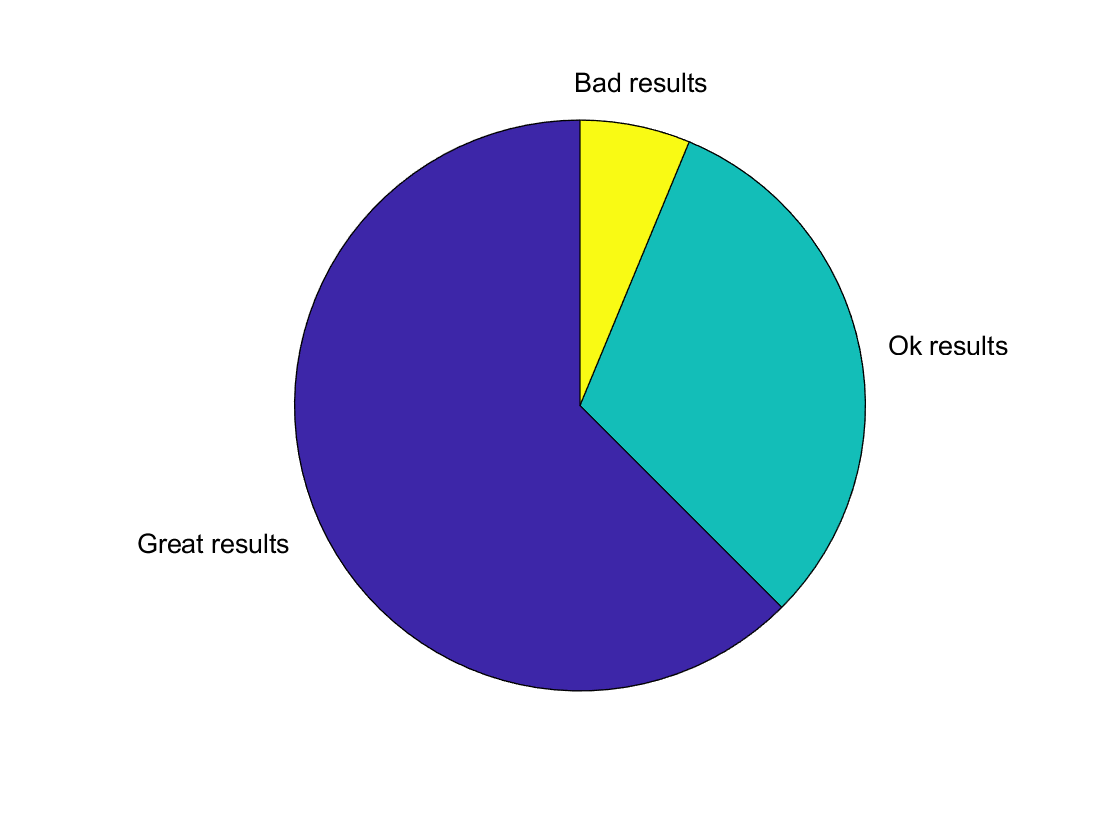

figure;
pie([10, 5, 1], ["Great results", "Ok results", "Bad results"]);

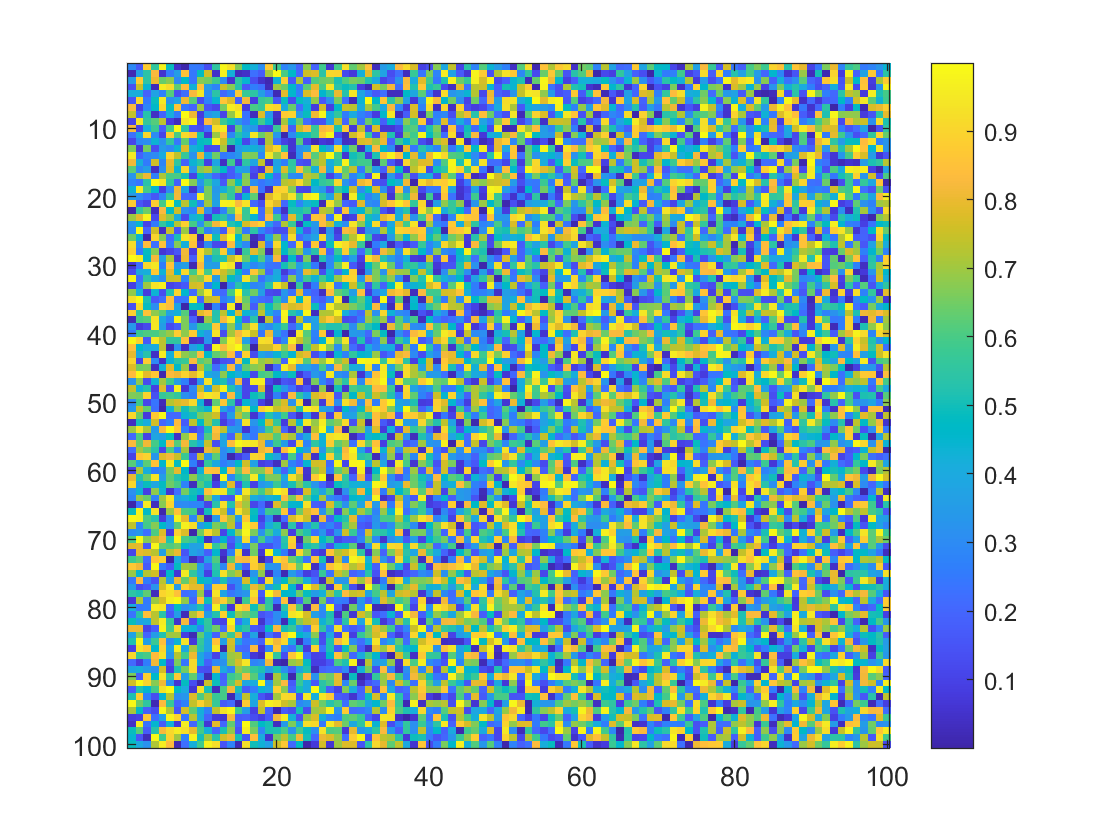

figure;
colors = rand(100, 100);
imagesc(colors);
colorbar;

This is the function I used to create a mandelbrot fractal!

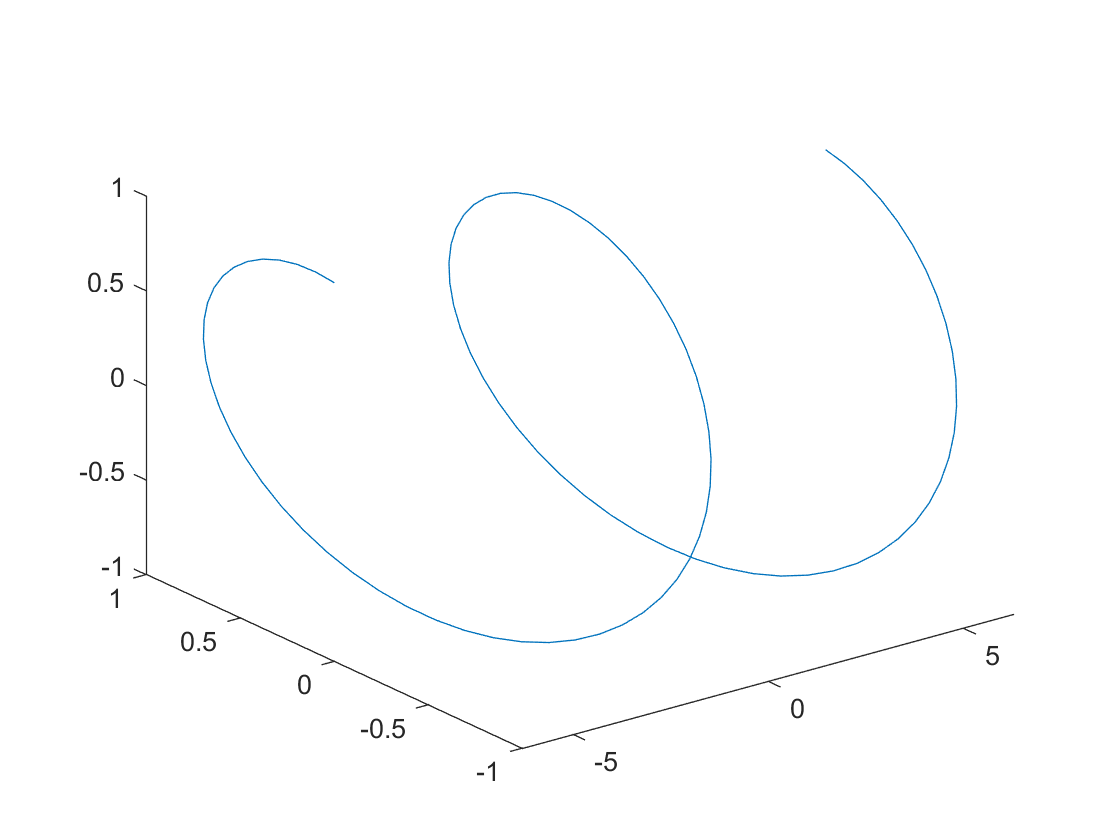

figure;
plot3(x, sin(x), cos(x));

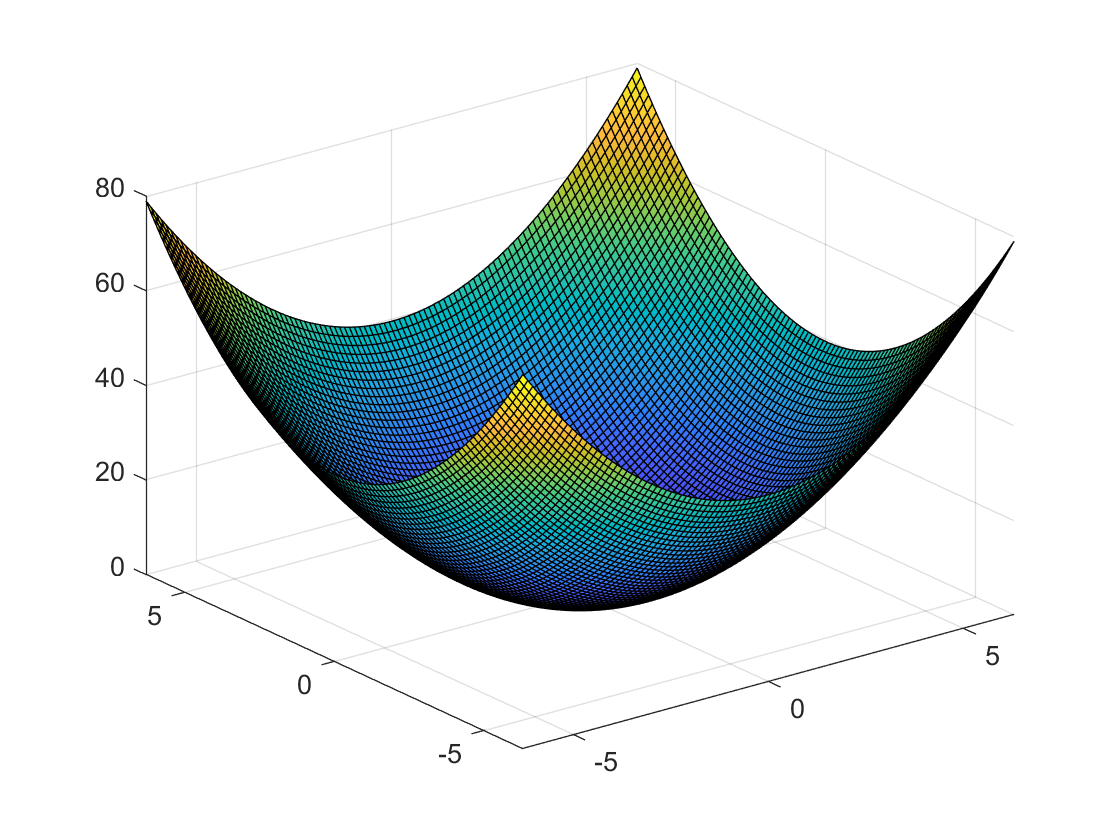

figure;
[x_mesh, y_mesh] = meshgrid(x, x);
surf(x_mesh, y_mesh, x_mesh.^2 + y_mesh.^2);

### Tables

There are many example data tables that come with MATLAB. Here is one:

tsunamis = readtable('tsunamis.xlsx');

Tables are great for plotting and data exploration. You can for example pass a table column into the `wordcloud` function.

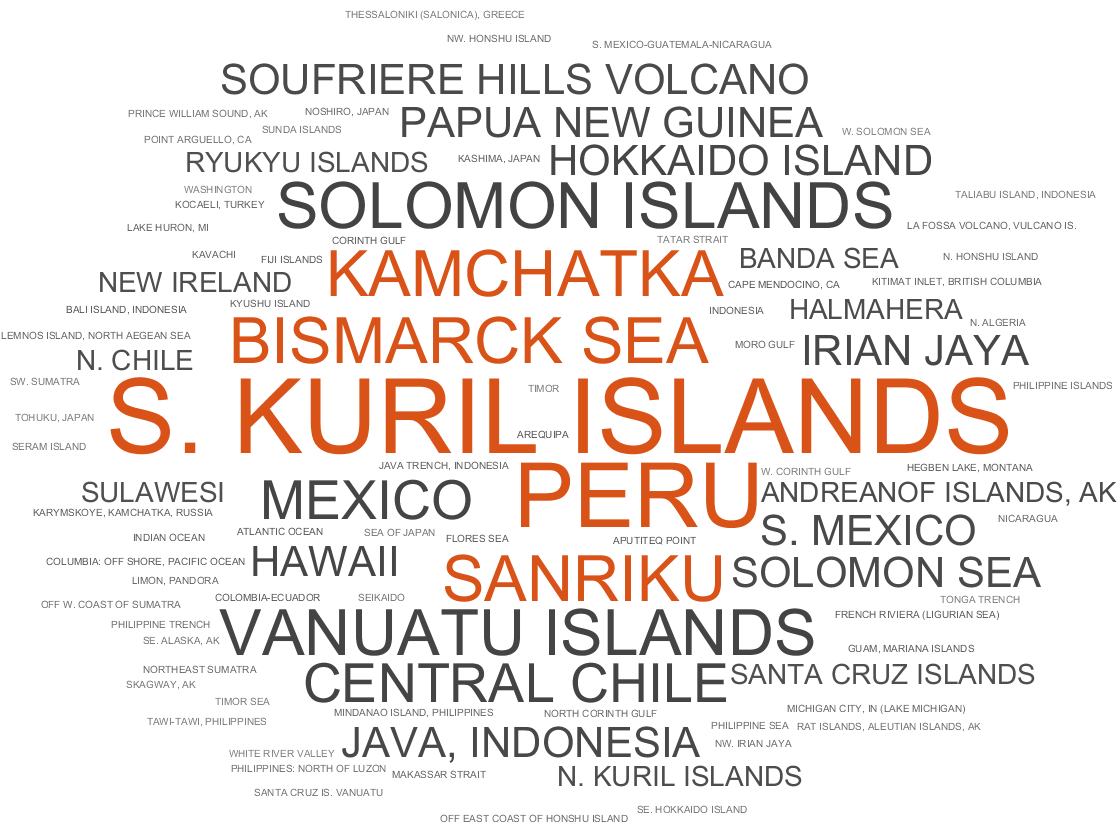

figure;
wordcloud(categorical(tsunamis.Location));

You can also explore the data by clicking on the variable and opening the plots ribbon.

## Customization

You can customize a plot by adding x labels, y labels etc.

figure;
ax = gca;
plot(ax, x, sin(x));

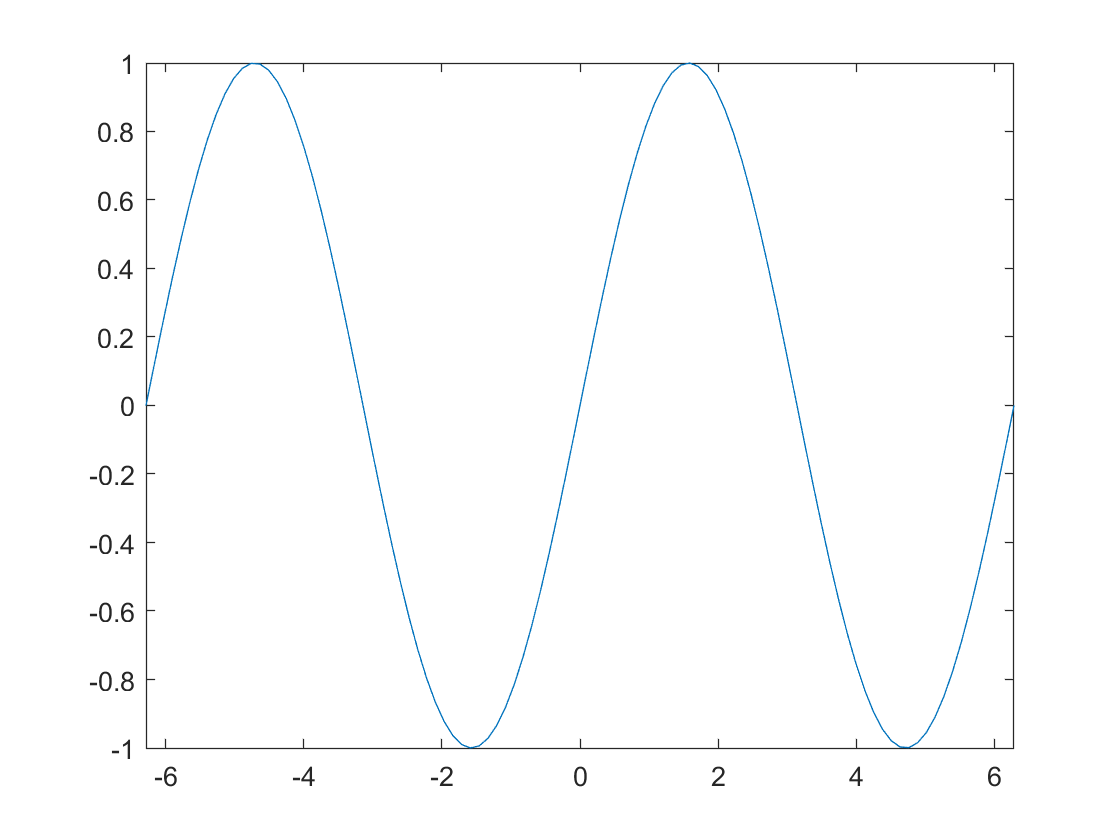

xlim(ax, [-2*pi, 2*pi]);

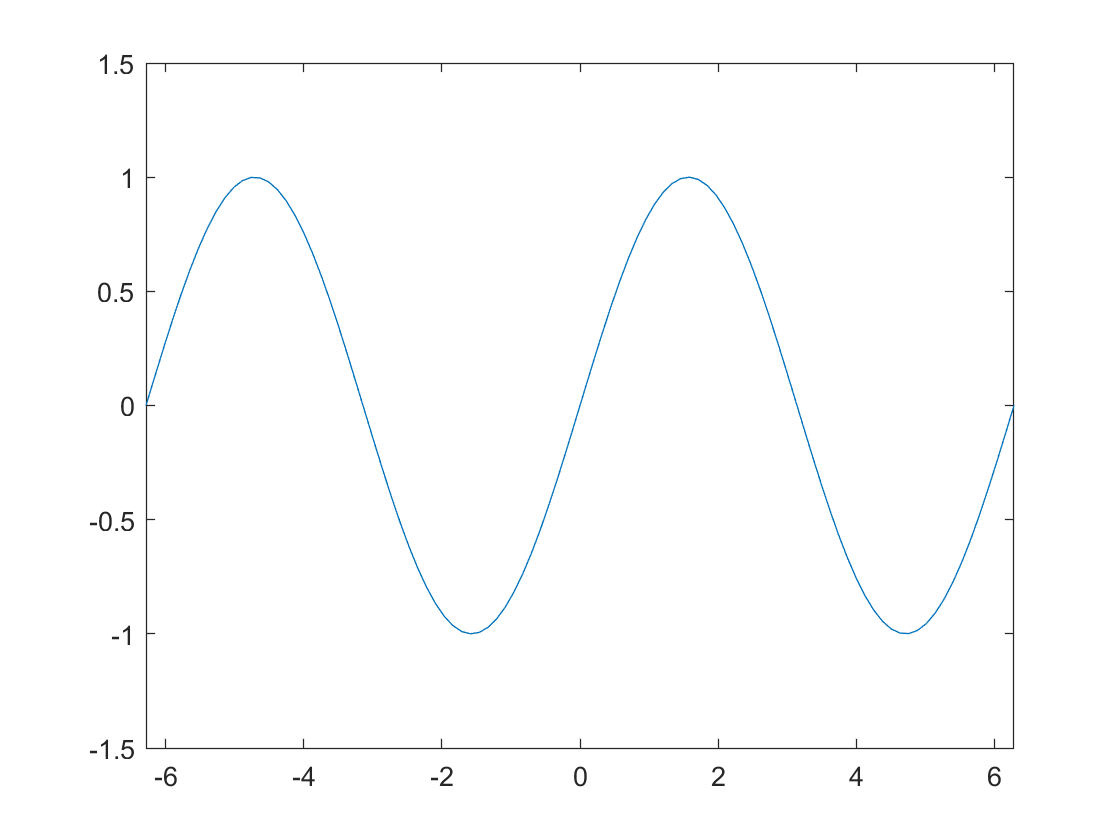

ylim(ax, [-1.5, 1.5]);

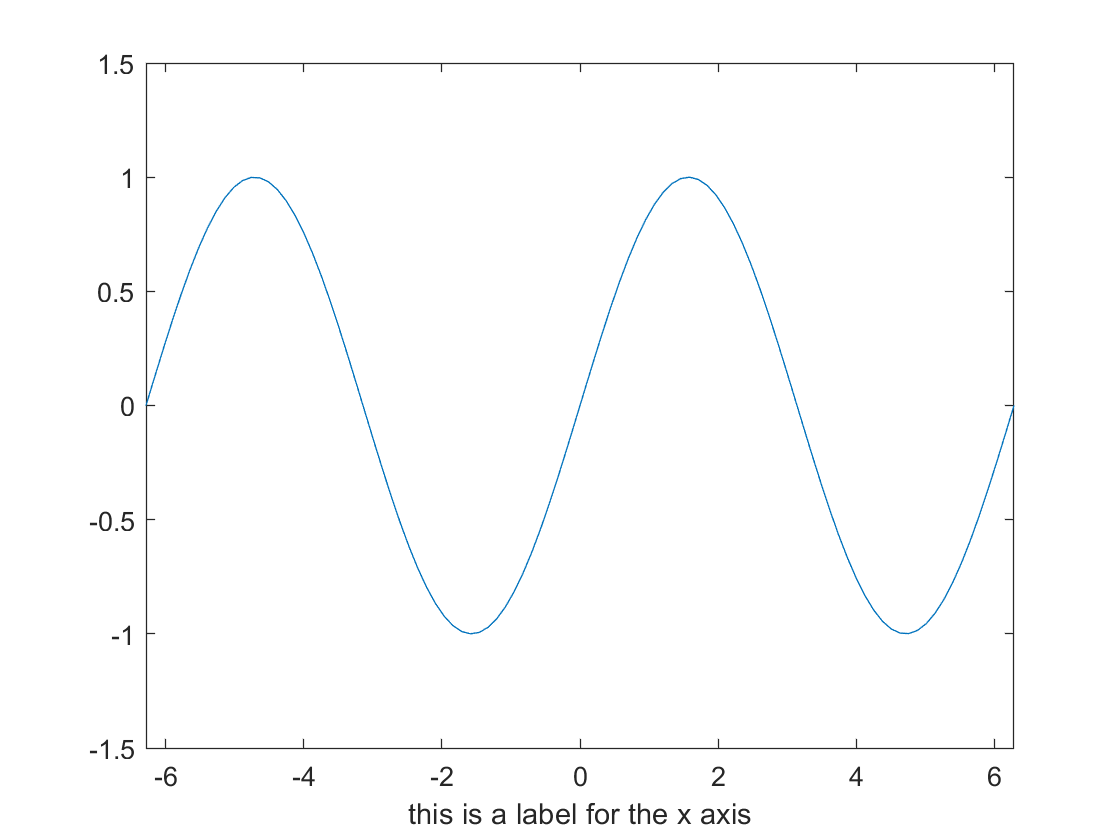

xlabel(ax, "this is a label for the x axis");

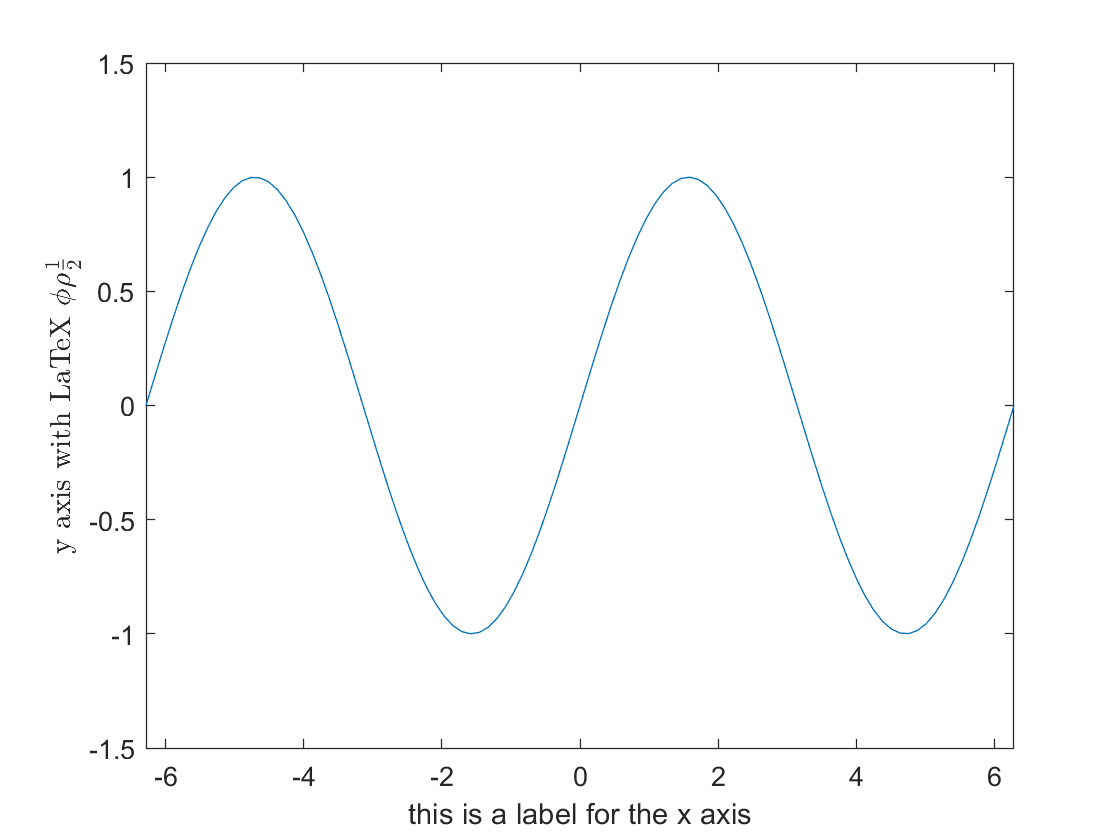

ylabel(ax, "y axis with LaTeX $\phi \rho \frac{1}{2}$", "Interpreter","latex");

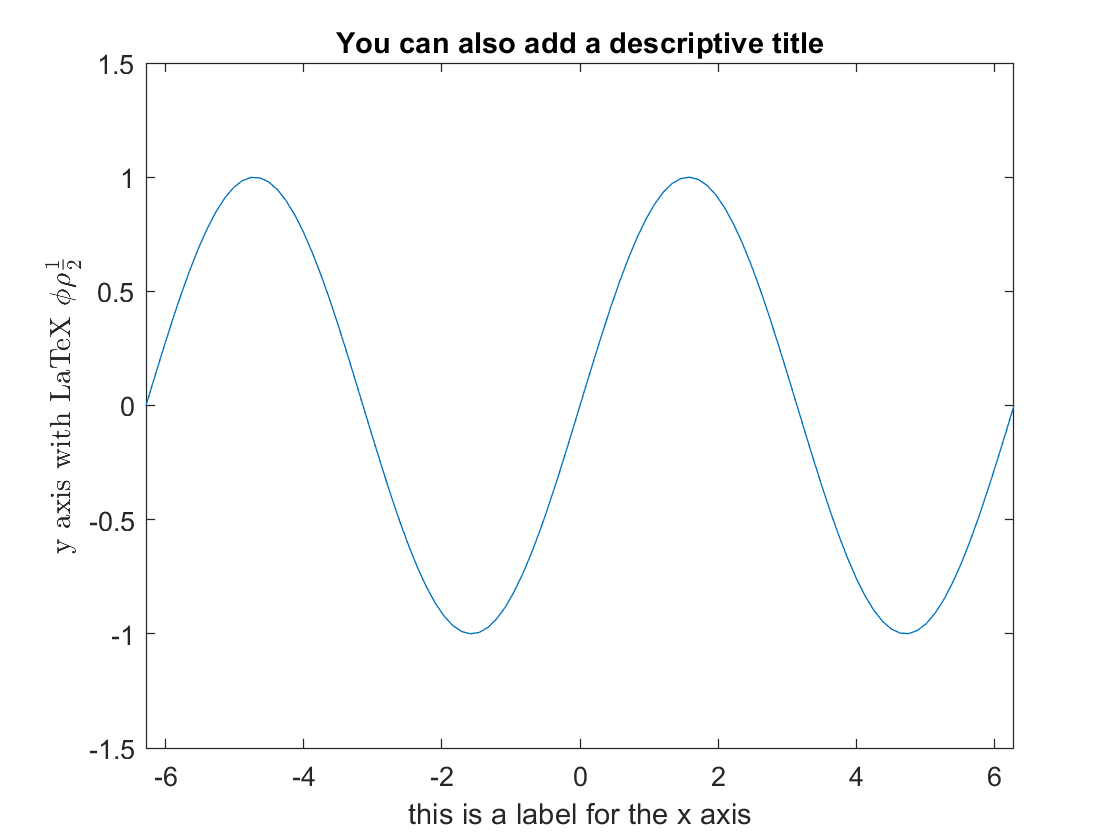

title(ax, "You can also add a descriptive title");

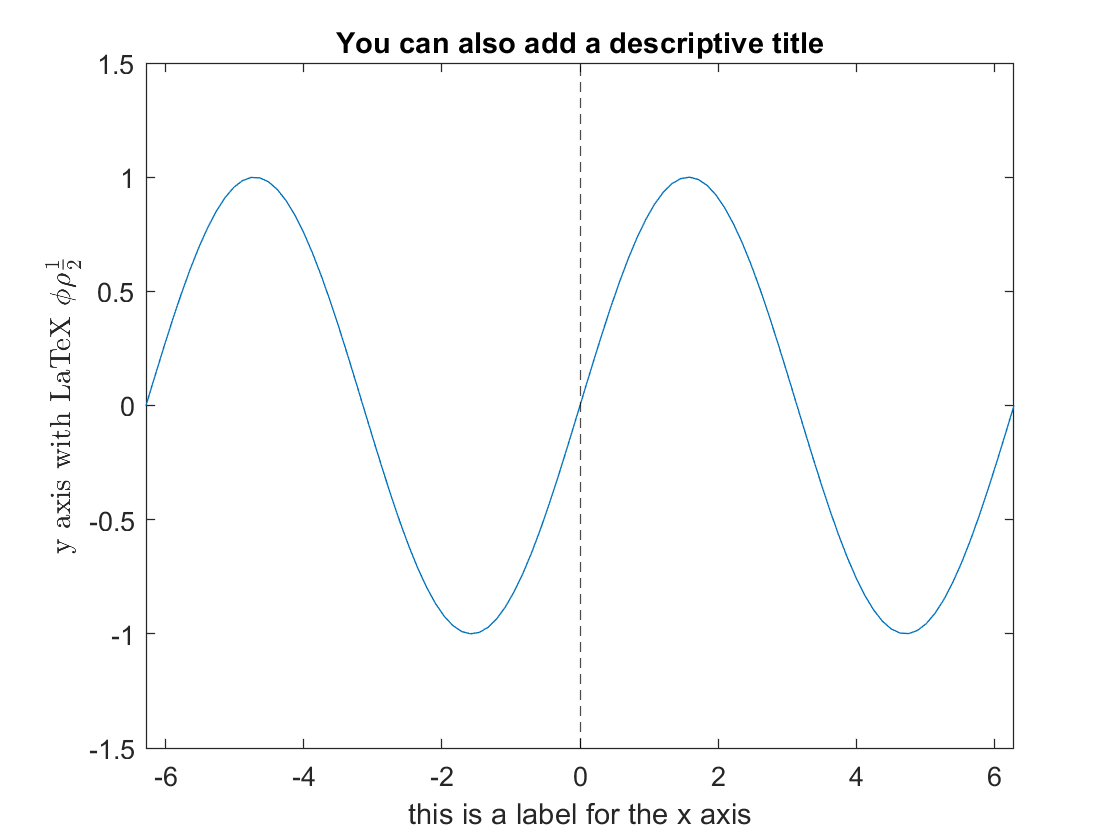

xline(ax, 0, "k--");

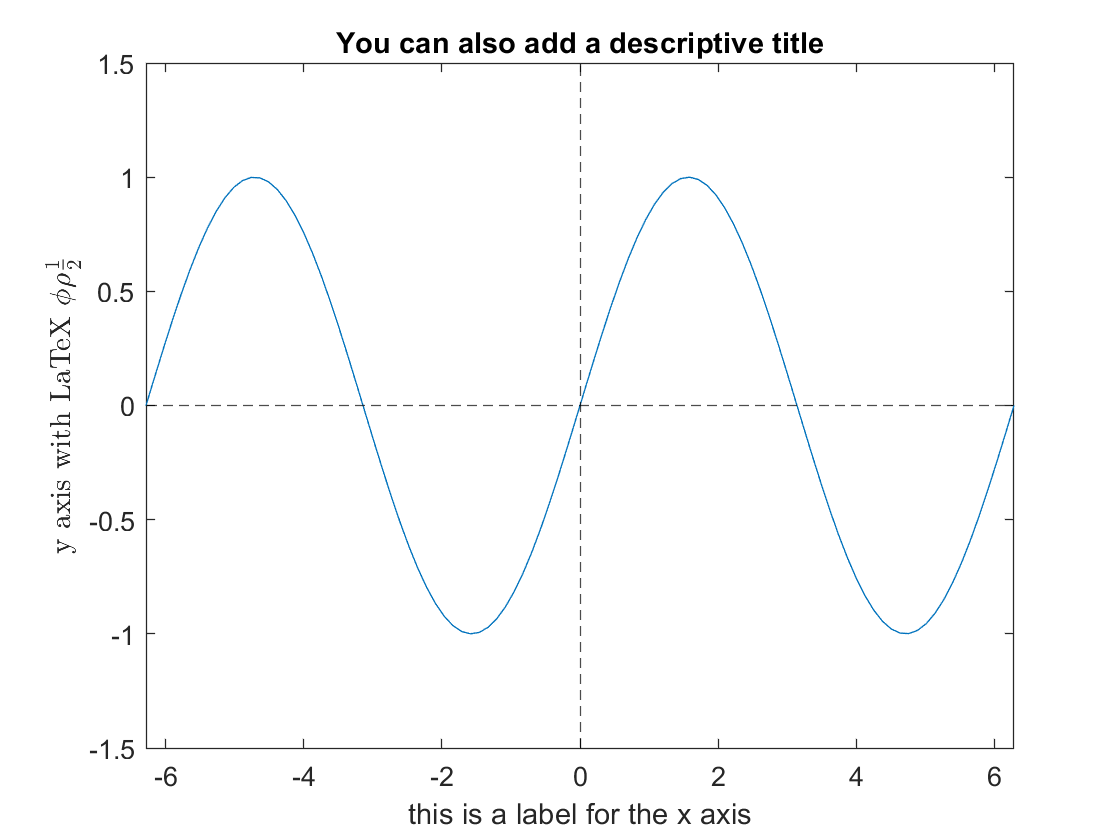

yline(ax, 0, "k--");

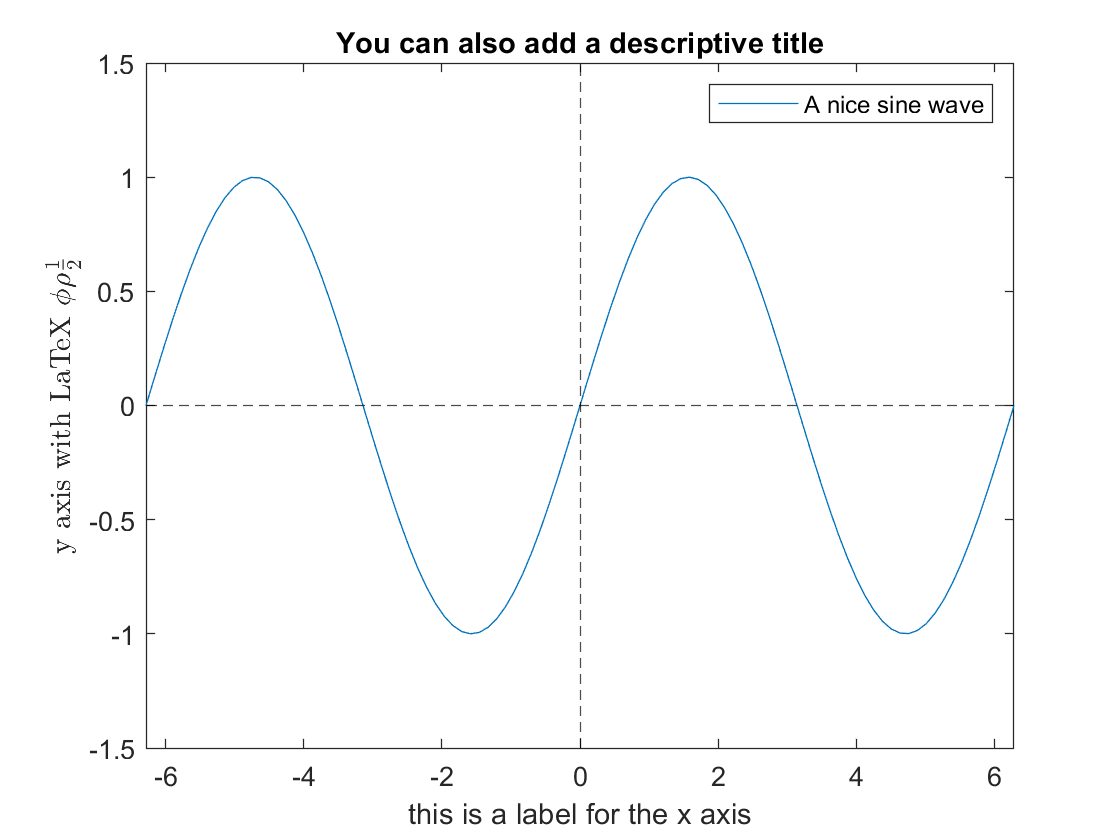

legend(ax, "A nice sine wave");

There are many different functions that you can use to save a figure in MATLAB, all of which do slightly different things.

exportgraphics(ax, "image.pdf") % Can save individual axes and not just an entire figure.
saveas(gcf, "image.png")        % Saves to a format other than fig, e.g., png, jpeg, svg etc.
savefig("matlab_native.fig")    % Saves as a fig object, which can be read by MATLAB
copygraphics(gcf)               % Copy image to the clipboard

A figure can also contain multiple axes. These can e.g., be created with `subplot`:

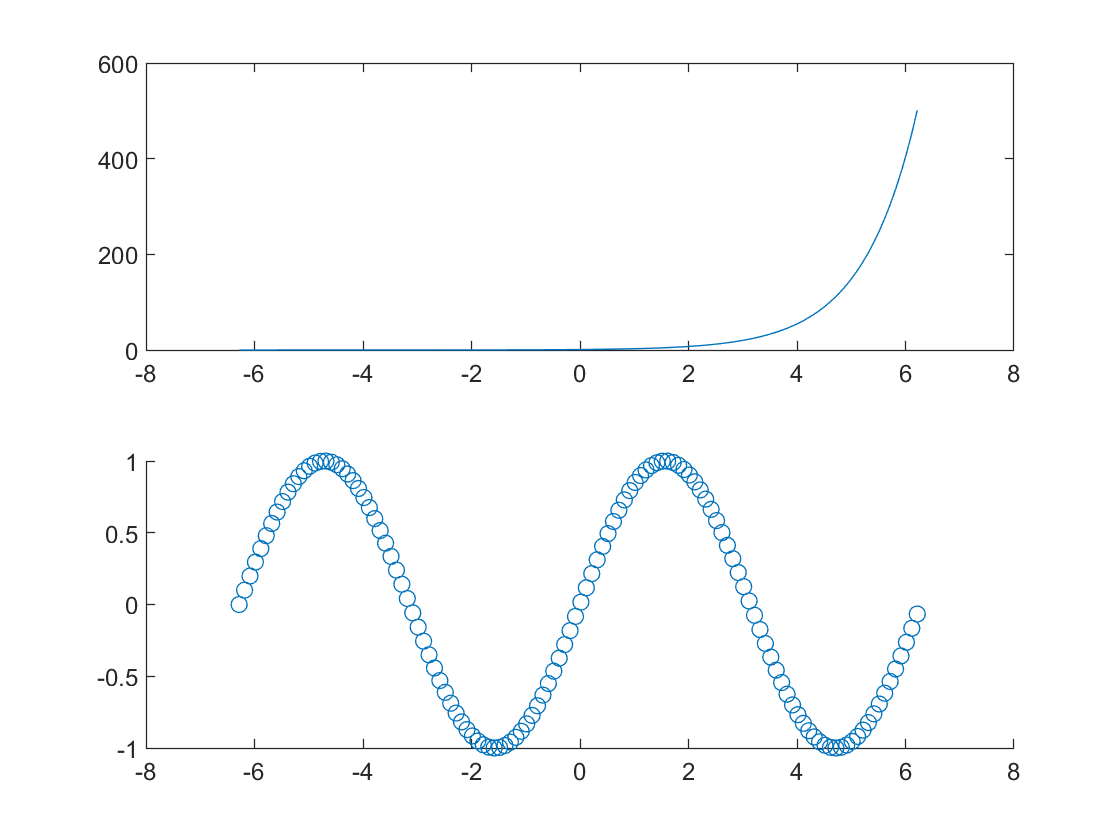

figure;
subplot(2, 1, 1);
plot(x, exp(x));
subplot(2, 1, 2);
scatter(x, sin(x));
exportgraphics(gcf, "multiax.png")

Or more recently, `tiledlayout` (which is often more clean)

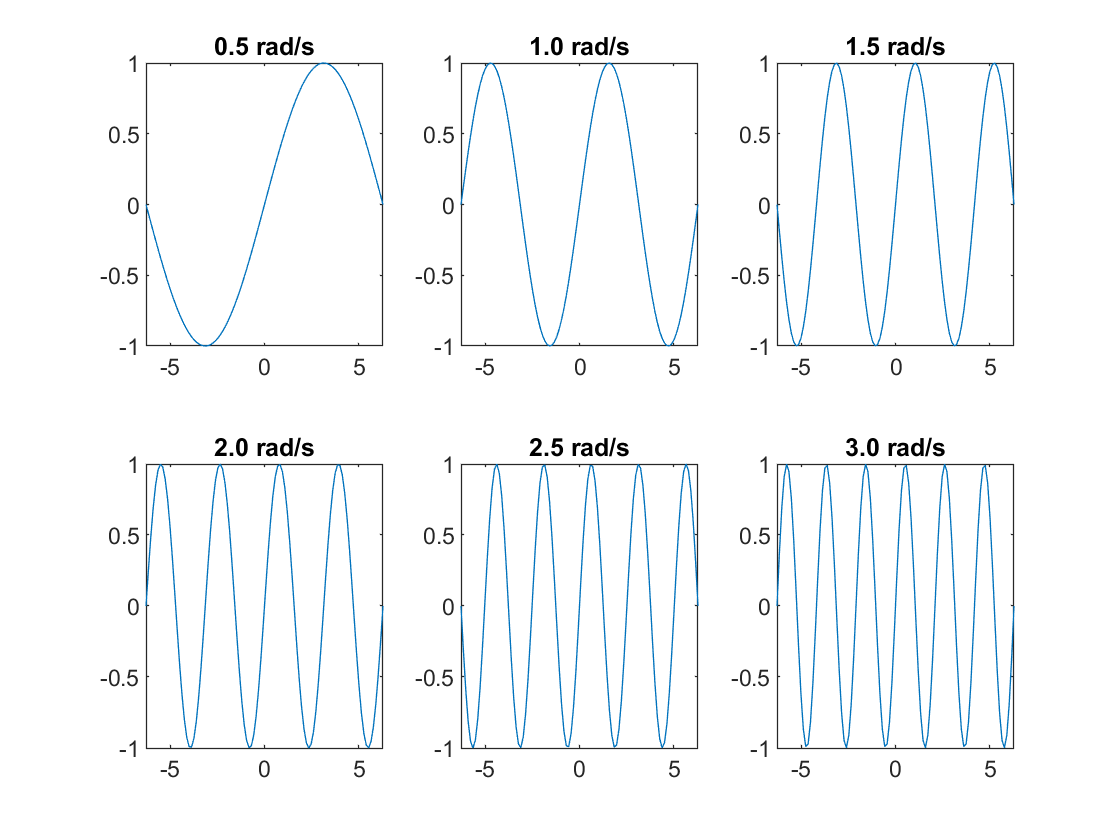

figure;
tiles = tiledlayout(2, 3);
for i = 1:2*3
    nexttile
    plot(x, sin(i/2 .* x));
    title(sprintf("%.1f rad/s", i/2));
end

## New features

These features were released **yesterday** (2021-09-23)! You must have MATLAB R2021b to be able to run these examples.

data = table(rand(50, 1), rand(50, 1));
data.Properties.VariableNames = {'x values', 'y values'}

data = 50×2 table
        x values              y values     
    _________________    __________________

    0.276718396567295     0.434621922778401
    0.145665094562066      0.88000025801773
    0.719139751387948     0.499519924895774
    0.755145537055251     0.568013278463339
    0.847926149368648    0.0875586815063482
    0.160876569003879     0.443955443636316
     0.42693028532815     0.704571197322385
    0.801657242185846     0.981805703472202
     0.20638453143481     0.358108399458237
    0.656937438648436     0.115318408331771
    0.290158896778862     0.260124943167344
    0.685802182830369     0.995279833529812
     0.30879215248787     0.837499321725222
    0.942700205261103     0.750067727239643
    0.238910324973161     0.764551235231723
    0.698779840616269     0.975703249931249


scatter(data, 'x values', 'y values');

Error using scatter (line 46)
Not enough input arguments.

## Easter Egg

Plot the MATLAB logo:

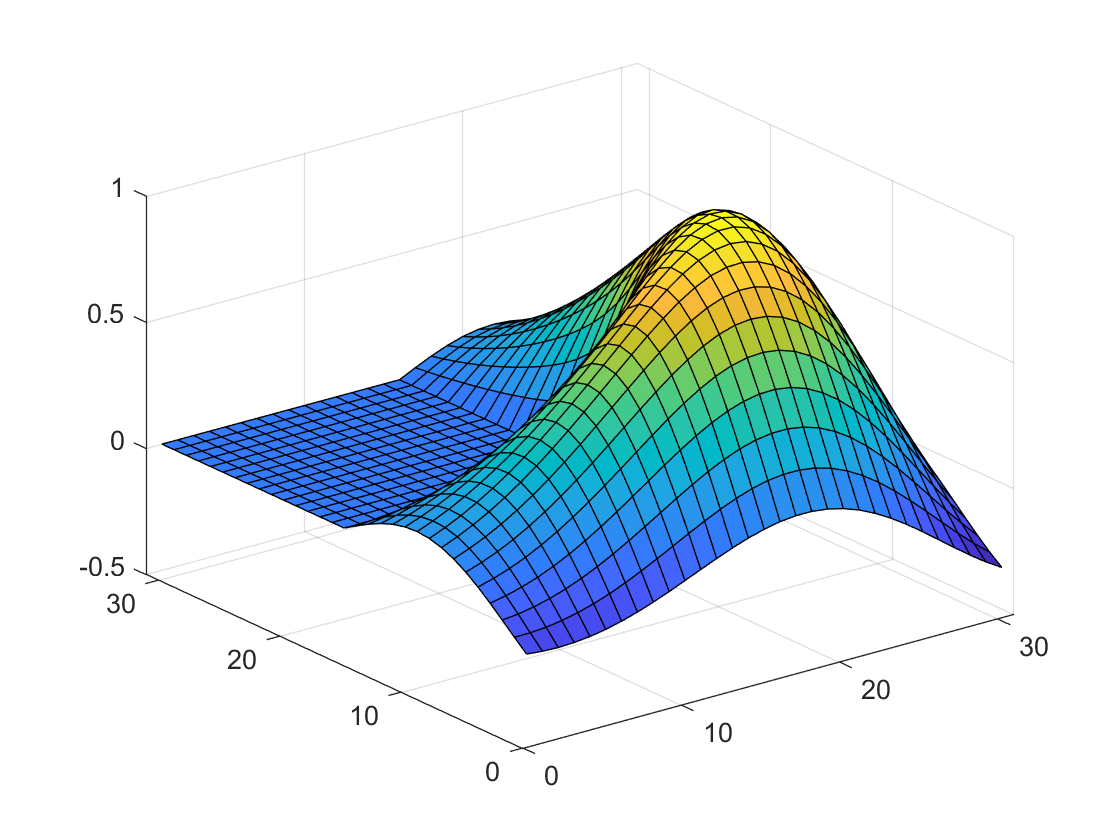

figure;
m = membrane;
surf(m);

## Extras

These will only be covered if time permits.

### Layout

A figure is separated into multiple parts: a figure, which contains axes objects, which contains plotted objects. This plotted object depends on which plotting function you call, e.g,, `plot`, `scatter`, `pie` etc.

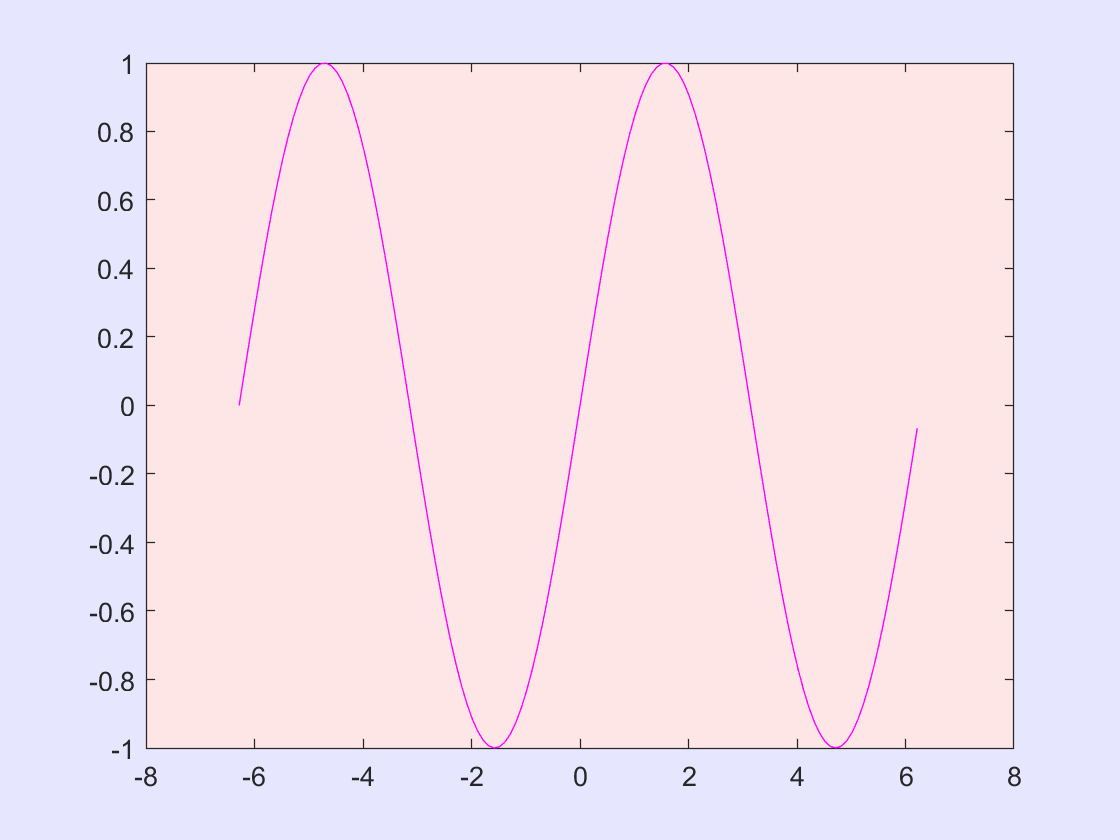

f = figure;
a = axes(f);
line = plot(a, x, sin(x));
a.Color = [1, 0.9, 0.9];  % light red
f.Color = [0.9, 0.9, 1];  % light blue
line.Color = [1, 0, 1];   % magenta

Their properties can also be changed with `set`:

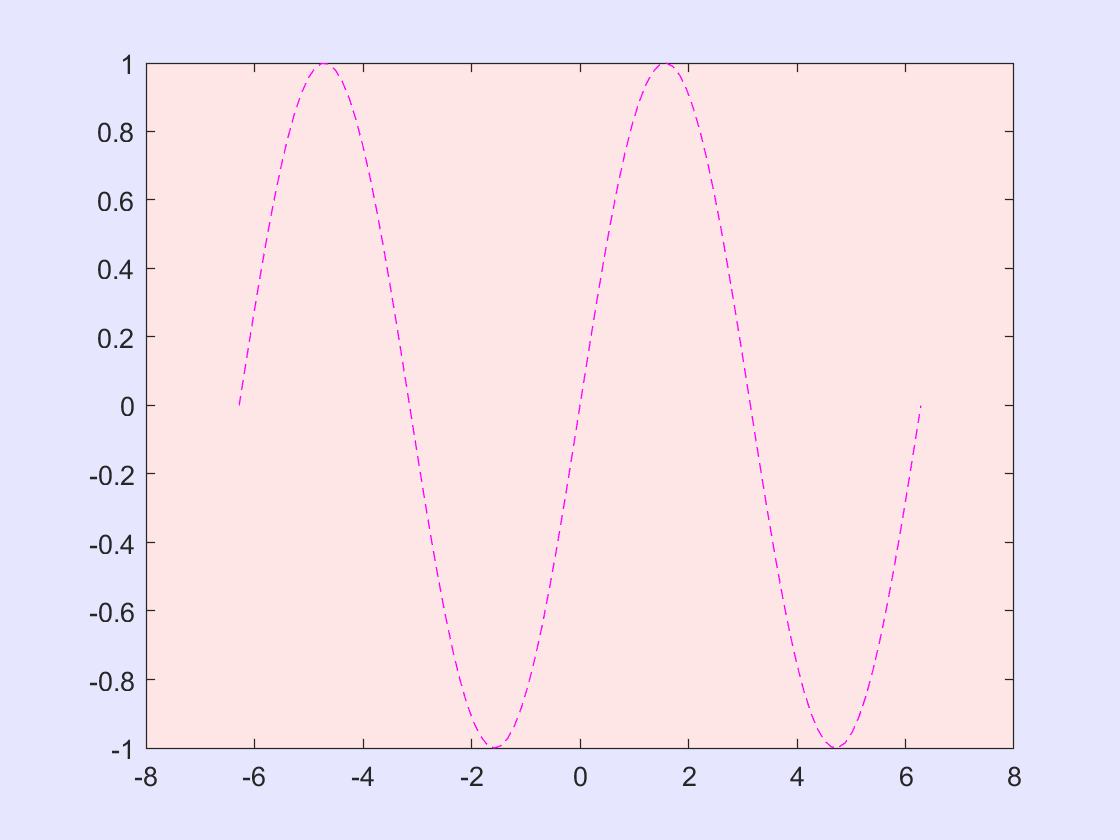

set(line, "LineStyle","--");

**Tip! **`set `or using the dot notation to update the data of a line when e.g., plotting is much more efficient than calling `plot` to rerender everything.

## Additional Resources

Want to learn more about this topic? Check out these links!

- [https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

- [https://www.mathworks.com/products/matlab/plot-gallery.html](https://www.mathworks.com/products/matlab/plot-gallery.html) 

- [https://www.mathworks.com/videos/visualizing-data-with-matlab-1567681462129.html](https://www.mathworks.com/videos/visualizing-data-with-matlab-1567681462129.html) 

- [https://www.mathworks.com/company/newsletters/articles/creating-specialized-charts-with-matlab-object-oriented-programming.html](https://www.mathworks.com/company/newsletters/articles/creating-specialized-charts-with-matlab-object-oriented-programming.html) 

- [https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html](https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html) 

# Conclusion

## Quiz Time!

Time for a Kahoot on the content of this presentation. Go to [https://kahoot.it](https://kahoot.it) and enter the code on the screen.

Top 3 winners will get Amazon gift cards:

- 250 SEK

- 150 SEK

- 100 SEK

## Merch Giveaway

Where? To the left of the **KTH library **entrance. Be on the lookout for a red backpack.

When? Monday **27th September 9:45-12:15**.

Who? **Everyone who participated **in this event can get merch.

## Emails

If you want an email before each event (no more, no less), fill in your email in this form: [https://forms.gle/Ln2y7wVVGxd9DvW47](https://forms.gle/Ln2y7wVVGxd9DvW47)  